clear
clc
format long

throttle=xlsread('motor.xlsx','B2:B54');
thrust=xlsread('motor.xlsx','C2:C54').*9.81;
power=xlsread('motor.xlsx','E2:E54');
a=polyfit(throttle,thrust,6)

a =   -0.000000000140675   0.000000030629785  -0.000002097995902   0.000032392358067   0.001982324981180   0.021260289345294   0.164761238254325


b=polyfit(throttle,power,6)

b =   -0.000000007965664   0.000001901136049  -0.000158961933757   0.005425679690860  -0.030524707578218   0.794872021052043   2.959442083749500


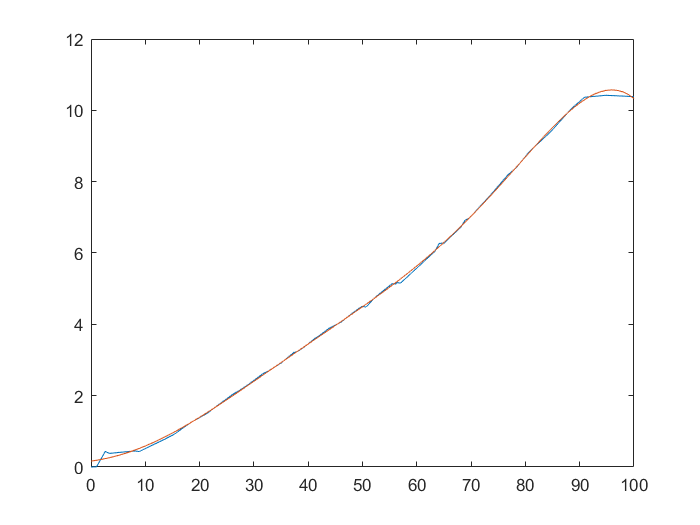



figure
plot(throttle,thrust)
hold on
plot(linspace(0,100),polyval(a,linspace(0,100)))

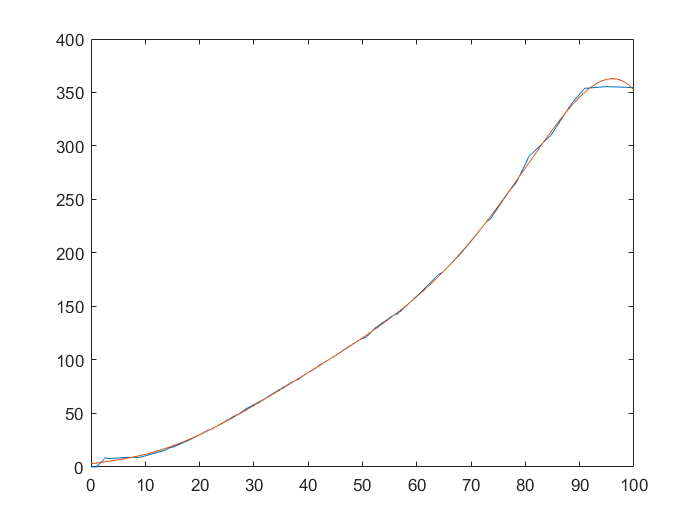


figure
plot(throttle,power)
hold on
plot(linspace(0,100),polyval(b,linspace(0,100)))


c=polyfit(thrust,throttle,6)

c =    0.000106460047187   0.001682145469029  -0.085966748628573   0.915086428052733  -4.301170611461207  19.048979026808645  -0.819624990299465


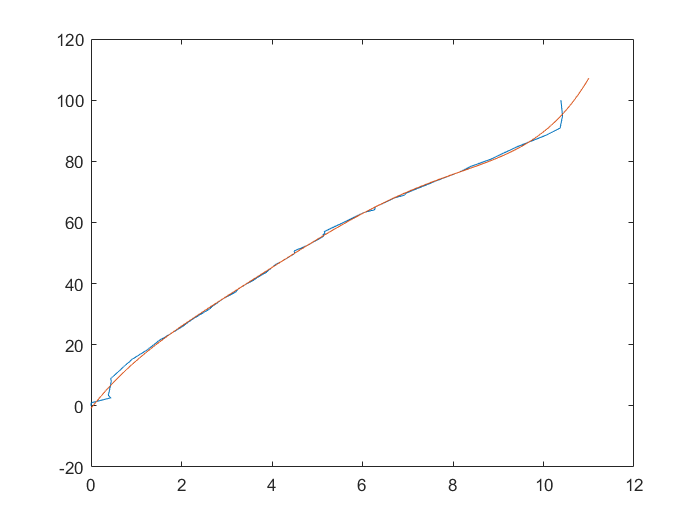


figure
plot(thrust,throttle)
hold on
plot(linspace(0,11),polyval(c,linspace(0,11)))

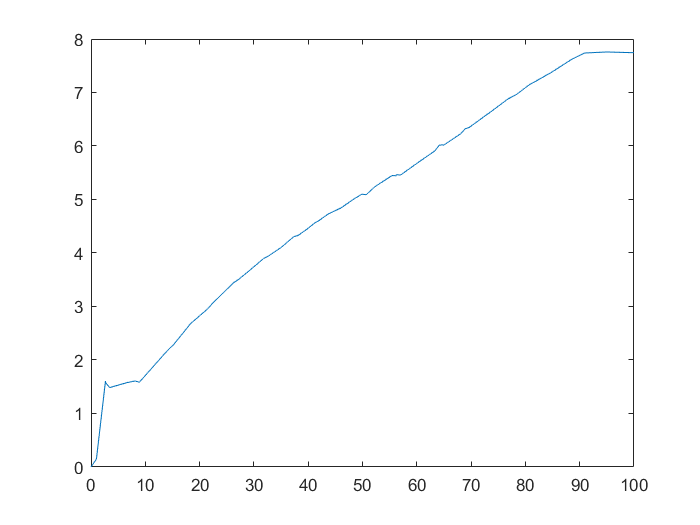


v_h=sqrt(thrust/(2*1.225*0.01767));
maxdv=0.5*v_h;

figure
plot(throttle,maxdv)